clear all;
clc;

% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% Created 28-Jun-2020 14:16:49
%
% This script assumes these variables are defined:
%
%   X - input data.
%   y - target data.

load ('E:\STUDY\Semester 7\PA\Program\tilesimage3.mat');

x = X';
t = y';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg'  % Scaled conjugate gradient backpropagation.

trainFcn = 'trainscg'


% Create a Pattern Recognition Network
hiddenLayerSize = 1000;
net = patternnet(hiddenLayerSize, trainFcn)


net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1000
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      


% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 10/100;
net.divideParam.testRatio = 10/100;

% Train the Network
[net,tr] = train(net,x,t)


net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 19002
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      

tr = struct with fields:
        trainFcn: 'trainscg'
      trainParam: [1×1 struct]
      performFcn: 'crossentropy'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×328 double]
          valInd: [14 33 52 53 61 67 79 127 132 140 144 154 156 162 173 174 180 182 199 230 249 257 261 263 272 282 292 301 317 328 329 334 345 347 352 356 359 374 393 401 402]
         testInd: [4 12 18 40 55 57 69 74 85 86 99 104 115 119 145 147 148 163 164 166 207 210 212 213 224 237 240 242 262 271 274 275 288 314 321 322 335 364 385 391 394]
            stop: 'Validation stop.'
      num_epochs: 35
       trainMask: {[2×410 double]}
         valMask: {[2×410 double]}
        testMask: {[2×410 double]}
      best_epoch: 29
            goal: 0
          states: {'epoch'  'time'  'perf'  'vperf'  'tperf'  'gradient'  'val_fail'}
           epoch: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 

%modelNN = [net,tr]

% Test the Network
y = net(x)

y =     0.7379    0.6641    0.4175    0.1982    0.1259    0.0682    0.6581    0.7954    0.6441    0.0053    0.1633    0.1966    0.7396    0.4732    0.7737    0.4888    0.2204    0.2295    0.2019    0.6242    0.5345    0.5174    0.7964    0.3563    0.3563    0.5382    0.5397    0.5557    0.7545    0.6071    0.6777    0.1572    0.2223    0.4732    0.4731    0.8041    0.8021    0.5787    0.4326    0.2314    0.4858    0.5581    0.0991    0.2518    0.5988    0.6464    0.7138    0.1834    0.9378    0.6105
    0.2621    0.3359    0.5825    0.8018    0.8741    0.9318    0.3419    0.2046    0.3559    0.9947    0.8367    0.8034    0.2604    0.5268    0.2263    0.5112    0.7796    0.7705    0.7981    0.3758    0.4655    0.4826    0.2036    0.6437    0.6437    0.4618    0.4603    0.4443    0.2455    0.3929    0.3223    0.8428    0.7777    0.5268    0.5269    0.1959    0.1979    0.4213    0.5674    0.7686    0.5142    0.4419    0.9009    0.7482    0.4012    0.3536    0.2862    0.8166    0.0622    0

e = gsubtract(t,y)

e =    -0.7379   -0.6641   -0.4175   -0.1982   -0.1259   -0.0682   -0.6581   -0.7954   -0.6441   -0.0053   -0.1633   -0.1966   -0.7396   -0.4732   -0.7737   -0.4888   -0.2204   -0.2295   -0.2019   -0.6242   -0.5345   -0.5174   -0.7964   -0.3563   -0.3563   -0.5382   -0.5397   -0.5557   -0.7545   -0.6071   -0.6777   -0.1572   -0.2223   -0.4732   -0.4731   -0.8041   -0.8021   -0.5787   -0.4326   -0.2314   -0.4858   -0.5581   -0.0991   -0.2518   -0.5988   -0.6464   -0.7138   -0.1834   -0.9378   -0.6105
    0.7379    0.6641    0.4175    0.1982    0.1259    0.0682    0.6581    0.7954    0.6441    0.0053    0.1633    0.1966    0.7396    0.4732    0.7737    0.4888    0.2204    0.2295    0.2019    0.6242    0.5345    0.5174    0.7964    0.3563    0.3563    0.5382    0.5397    0.5557    0.7545    0.6071    0.6777    0.1572    0.2223    0.4732    0.4731    0.8041    0.8021    0.5787    0.4326    0.2314    0.4858    0.5581    0.0991    0.2518    0.5988    0.6464    0.7138    0.1834    0.9378    0

performance = perform(net,t,y)

performance = 0.2463

tind = vec2ind(t)

tind =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


yind = vec2ind(y)

yind =      1     1     2     2     2     2     1     1     1     2     2     2     1     2     1     2     2     2     2     1     1     1     1     2     2     1     1     1     1     1     1     2     2     2     2     1     1     1     2     2     2     1     2     2     1     1     1     2     1     1


percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 0.2366

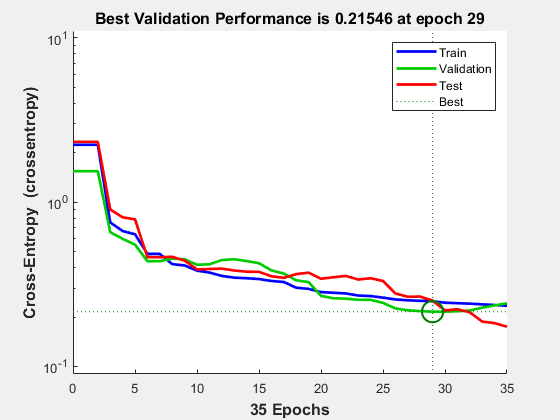


% View the Network
view(net)

% Plots
% Uncomment these lines to enable various plots.
figure, plotperform(tr)

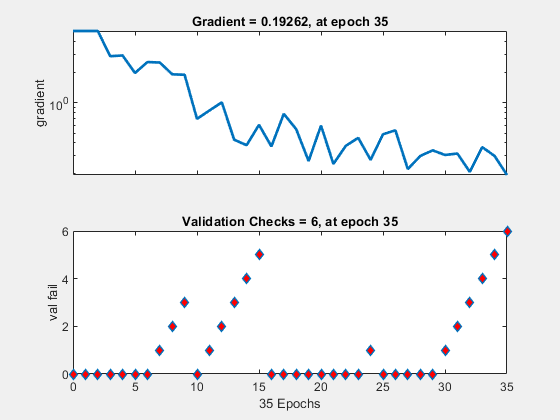

figure, plottrainstate(tr)

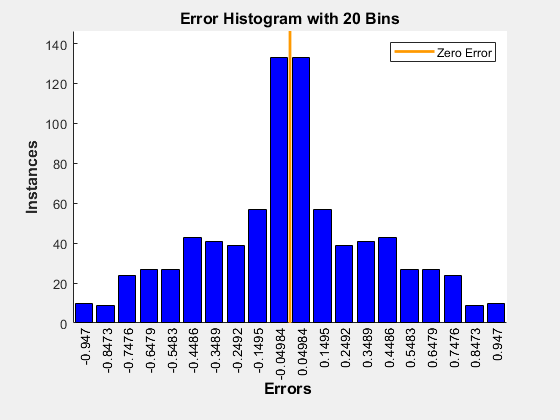

figure, ploterrhist(e)

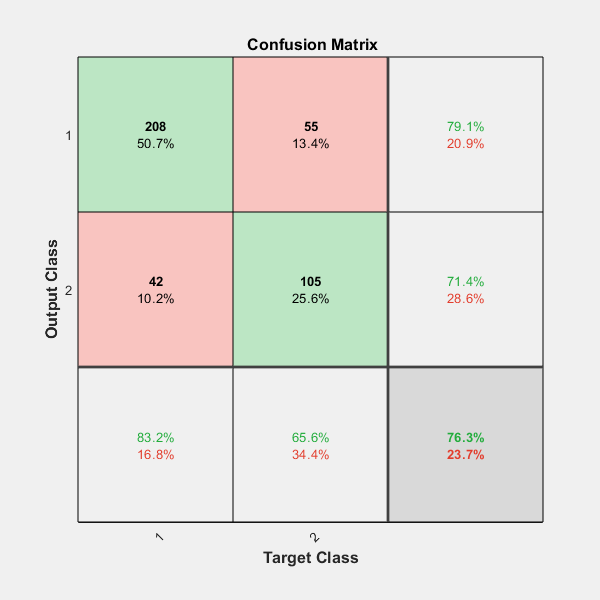

figure, plotconfusion(t,y)

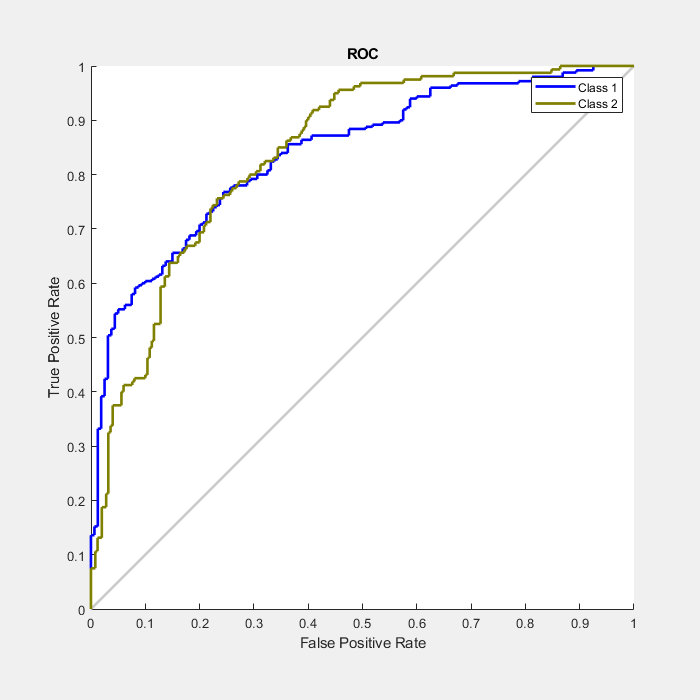

figure, plotroc(t,y)